**Computer Exercise 5.1.5**

The following program will apply the composite trapezoid algorithm with uniform spacing to $f(x) = \frac{\sin(x)}{x}$ from $x = 0$ to $x = \infty$. Since $f(x)$ is undefined at $x=0$ and (of course) $x=\infty$, we will have to approximate these 'endpoints' with a small and big value respectively. An approximation will then be made to the same function by using the following change of variables $x = \frac{1}{t}$ to the same function.  The corresponding approximations, actual values, and errors will be displayed.

%initiate function
f = @(x) sin(x)/x;

%%%initiate parameters
exponent = 6;
n = 10^(exponent);

%small number to approximate zero
a = 10^(-exponent);
%big number to approximate 'infinity'
b = n;

%known actual value
actual = pi/2;

%execute algorithm
I1 = Trapezoid_Uniform(f, a, b, n);

%display approximation
fprintf('integral approximation = %12.12f, acutal = %12.12f, error = %8.8e', ...

integral approximation = 1.570794497499, acutal = 1.570796326795, error = 1.82929585e-06

    I1, actual, abs(actual - I1))

This approximation is decent compared to the actual value: $\pi/2$.

Now by making the change of variable, we get:


$$x = \frac{1}{t} \ \Rightarrow$$
 
$$\int_{0}^{\infty} \frac{\sin(x)}{x}dx = \int_{x=0}^{x=\infty} \frac{\sin(1/t)}{(1/t)}\bigg(\frac{-1}{t^2}\bigg)dt = \int_{\infty}^{0} \frac{-\sin(1/t)}{t}dt =
\int_{0}^{\infty} \frac{\sin(1/t)}{t}dt $$
 

%initiate function
f = @(t) sin((1/t))/t;

%%%initiate parameters
exponent = 6;
n = 10^(exponent);

%small number to approximate zero
a = 10^(-exponent);
%big number to approximate 'infinity'
b = n;

%known actual value
actual = pi/2;

%execute algorithm
I2 = Trapezoid_Uniform(f, a, b, n);

%display approximation
fprintf('integral approximation = %12.12f, acutal = %12.12f, error = %8.8e', ...

integral approximation = -174995.278262264415, acutal = 1.570796326795, error = 1.74996849e+05

    I2, actual, abs(actual - I2))

That is a terrible approximation. What is going on? Perhaps plotting out the functions will help out.

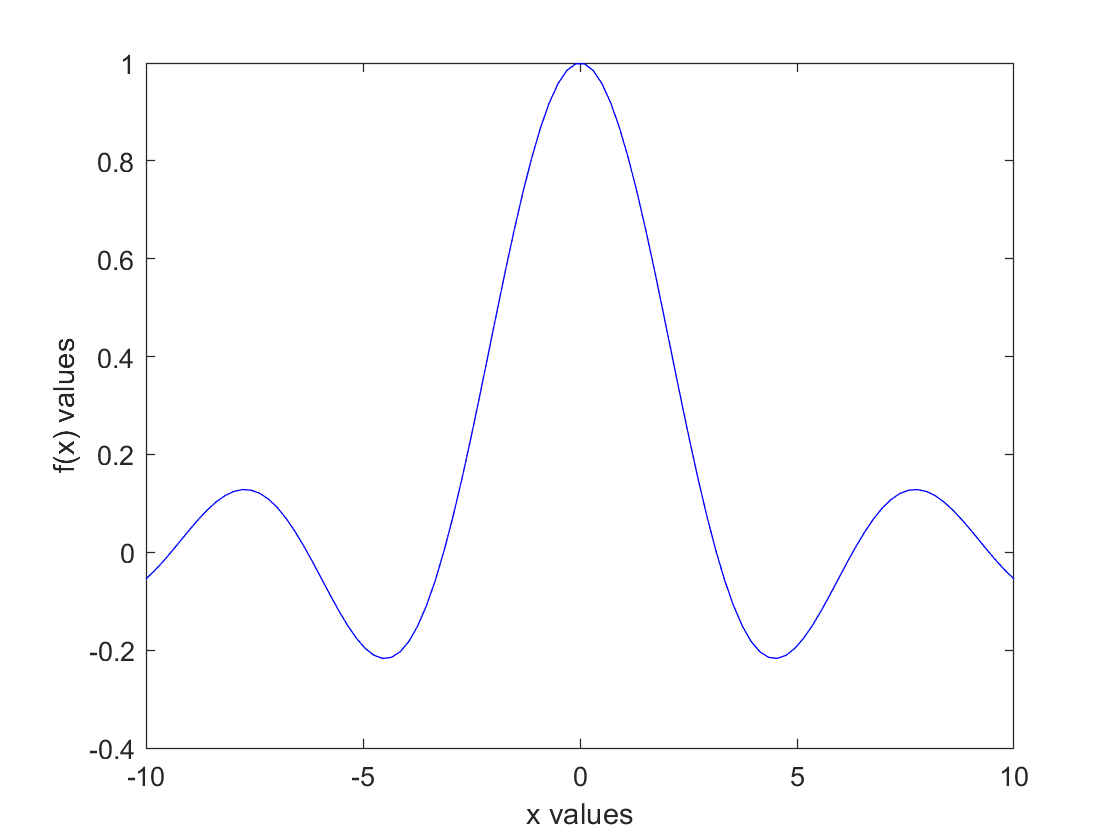

tvals = linspace(-1,1, 4500);
xvals = linspace(-10, 10);
yvals1 = sin(xvals)./xvals;
yvals2 = sin(1./tvals)./tvals;

figure(1)
plot(xvals, yvals1, "Color", 'b')
xlabel('x values')
ylabel('f(x) values')

Here is the function plotted out before the change of variables from $x = -10$ to $x=10$. It is symmetric and well behaved near zero despite being undefined there.

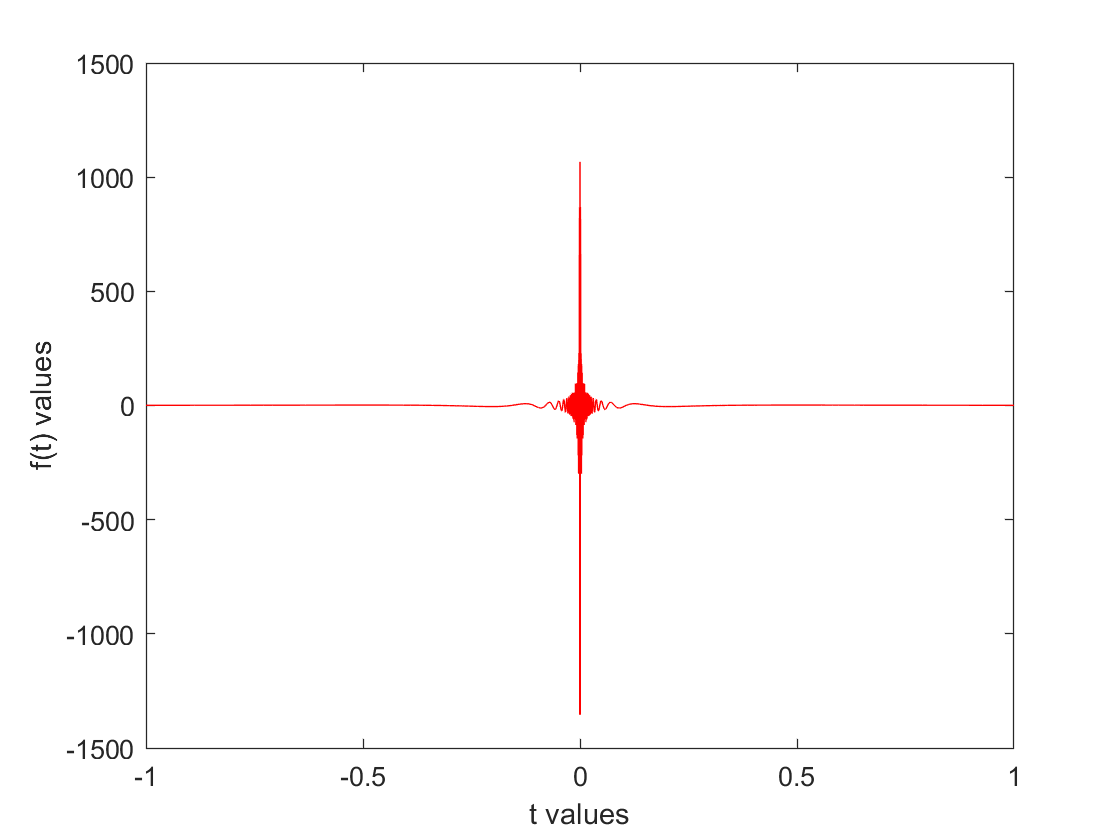

figure(2)
plot(tvals, yvals2, "Color",'r')
xlabel('t values')
ylabel('f(t) values')

However, here is the plot for $f(t) = \frac{\sin(1/t)}{t}$ plotted out over 4500 points from $t=-1$ to $t = 1$. It is clear that the function is terribly behaved near zero (increasing the amount of points increases the range substantially) which explains our lack of convergence after the change of variables.

function I = Trapezoid_Uniform(f, a, b, n)
    h = ((b-a)/n);
    sum = (1/2)*(f(a) + f(b));
    for k = 1:(n-1)
        xk = a + k*h;
        sum = sum + f(xk);      
    end
    I = h*sum;
end